# Punto 2

## 2.Diagonally scaled steepest descent method

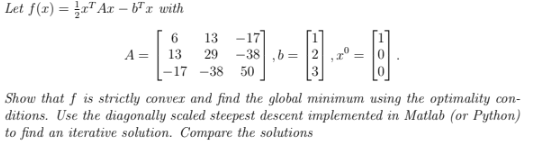

% Declaración de variables simbólicas
syms x1 x2 x3 real
x = [x1; x2; x3]

% Matriz A y vector b
A = [6, 13, -17;
     13, 29, -38;
     -17, -38, 50]

A =      6    13   -17
    13    29   -38
   -17   -38    50


b = [1; 2; 3]

b =      1
     2
     3



% Función f(x)
f1 = (1/2) * x.' * A * x - b.' * x

#### Demostrar que es convexa

La convexidad de f(x) se evalúa comprobando si la matriz A es definida positiva. Esto se logra mediante el cálculo de los valores propios de A. En este caso, los valores propios resultan ser positivos, lo que confirma que A es definida positiva y, por lo tanto, la función f(x) es convexa. Esto garantiza la existencia de un único mínimo global.

% Gradiente (primera derivada)
grad_f = gradient(f1, x);
disp('Gradiente de f(x):');

Gradiente de f(x):


disp(grad_f);

% Hessiana (segunda derivada), es la misma matriz A
Hessian_f = hessian(f1, x);
disp('Hessiana de f(x):');

Hessiana de f(x):


disp(Hessian_f);

% 1. Verificación con valores propios
fprintf('1. Verificación de definida positiva usando valores propios:\n');

1. Verificación de definida positiva usando valores propios:


eigenvalues = eig(A);  % Calcula los valores propios de A
disp('Valores propios de A:');

Valores propios de A:


disp(eigenvalues);

    0.0588
    0.2007
   84.7405




if all(eigenvalues > 0)
    fprintf('La matriz A es definida positiva porque todos sus valores propios son positivos.\n\n');
else
    fprintf('La matriz A no es definida positiva porque no todos sus valores propios son positivos.\n\n');
end

La matriz A es definida positiva porque todos sus valores propios son positivos.



#### Hallar el mínimo global con las Condiciones de optimalidad

El mínimo global se encuentra resolviendo el sistema de ecuaciones Ax=b. Al resolver este sistema, se obtiene el punto x∗ donde la función alcanza su valor mínimo. Este resultado es consistente con las condiciones de optimización de primer orden, que indican que el gradiente de f(x) debe ser cero en el punto óptimo.

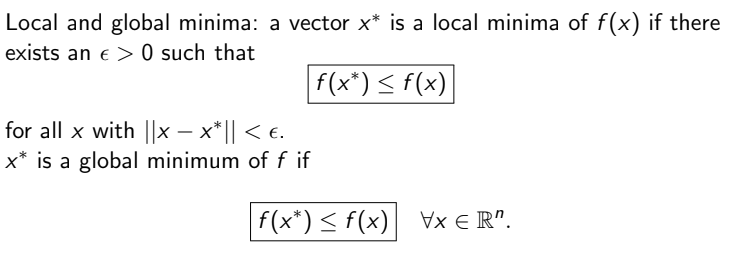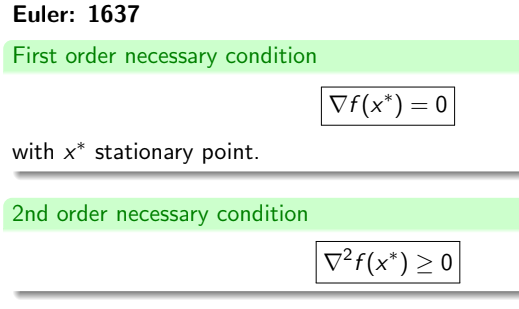

X = A \ b; % Este comando en Matlab resuelve las ecuaciones de forma Ax=B.
% Mostrar el resultado
disp('El mínimo global de la función se alcanza en:');

El mínimo global de la función se alcanza en:


disp(X);

   -5.0000
   39.0000
   28.0000




%Verificación
F=(1/2) * X.' * A * X - b.' * X

F = -78.5000

F2=gradient(F)

F2 = 0

#### Método de descenso más pronunciado en escala diagonal

Para aproximar el mínimo, se utiliza el método de descenso más pronunciado con una matriz de escala diagonal. Este método ajusta las actualizaciones de las variables x1,x2,x3� según las derivadas parciales y una matriz diagonal D, cuyos elementos están basados en los inversos de los elementos diagonales de A. Esto permite manejar mejor las diferencias de escala entre las variables.

La convergencia del método se verifica cuando el gradiente se vuelve suficientemente pequeño, indicando que se ha alcanzado una aproximación al mínimo.

grad_x1 = @(x1,x2,x3) (6*x1 + 13*x2 - 17*x3 - 1)

grad_x1 = function_handle with value:
    @(x1,x2,x3)(6*x1+13*x2-17*x3-1)


grad_x2 = @(x1,x2,x3) (13*x1 + 29*x2 - 38*x3 - 2)

grad_x2 = function_handle with value:
    @(x1,x2,x3)(13*x1+29*x2-38*x3-2)


grad_x3 = @(x1,x2,x3) (50*x3 - 38*x2 - 17*x1 - 3)

grad_x3 = function_handle with value:
    @(x1,x2,x3)(50*x3-38*x2-17*x1-3)



f2=matlabFunction(f1)

f2 = function_handle with value:
    @(x1,x2,x3)-x1-x2.*2.0-x3.*3.0+x1.*(x1.*3.0+x2.*(1.3e+1./2.0)-x3.*(1.7e+1./2.0))-x3.*(x1.*(1.7e+1./2.0)+x2.*1.9e+1-x3.*2.5e+1)+x2.*(x1.*(1.3e+1./2.0)+x2.*(2.9e+1./2.0)-x3.*1.9e+1)


% Valores iniciales
pts2(1,1) = 1;  % Valor inicial para x1
pts2(1,2) = 0;  % Valor inicial para x2
pts2(1,3) = 0;  % Valor inicial para x3
step = 0.6           % Paso (alpha)

step = 0.6000

max_iters = 30000       % Número máximo de iteraciones

max_iters = 30000

tolerancia = 1e-3      % Tolerancia para la convergencia

tolerancia = 1.0000e-03

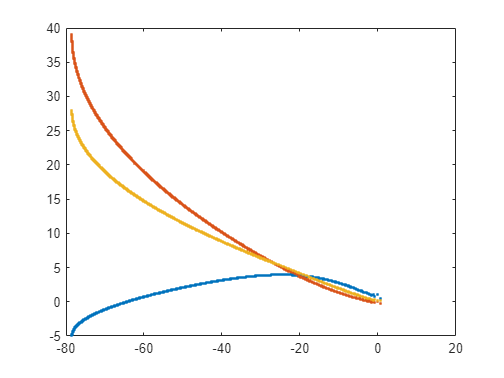

% Algoritmo de descenso más pronunciado con escala diagonal
i = 1;
for i = 1:max_iters
    % Gradiente en el punto actual
    gradix1 = grad_x1(pts2(i,1), pts2(i,2),pts2(i,3));  % Evaluar derivada parcial en x1
    gradix2 = grad_x2(pts2(i,1), pts2(i,2),pts2(i,3));  % Evaluar derivada parcial en x2
    gradix3 = grad_x3(pts2(i,1), pts2(i,2),pts2(i,3));  % Evaluar derivada parcial en x3

    % Escala diagonal D (tomamos la diagonal de A, en este caso como ejemplo, la diagonal de A)
    D = diag([1/A(1,1), 1/A(2,2), 1/A(3,3)]);  % Usamos las primeras dos entradas de la matriz A

    % Calculamos el siguiente paso de x1 y x2 (descenso con escala diagonal)
    pts2(i+1,1) = pts2(i,1) - step * D(1,1) * gradix1; % Actualización de x1
    pts2(i+1,2) = pts2(i,2) - step * D(2,2) * gradix2; % Actualización de x2
    pts2(i+1,3) = pts2(i,3) - step * D(3,3) * gradix3; % Actualización de x3
    % Visualización de la evolución de las variables
    plot( f2(pts2(i+1,1), pts2(i+1,2), pts2(i+1,3)), pts2(i+1,1), '.-', 'LineWidth', 1, 'Color', '#0072BD', 'DisplayName', 'x1');
    hold on;
    plot( f2(pts2(i+1,1), pts2(i+1,2), pts2(i+1,3)), pts2(i+1,2), '.-', 'LineWidth', 1, 'Color', '#D95319', 'DisplayName', 'x2');
    hold on;
    plot( f2(pts2(i+1,1), pts2(i+1,2), pts2(i+1,3)), pts2(i+1,3), '.-', 'LineWidth', 1, 'Color', '#EDB120', 'DisplayName', 'x3');
    hold on;
    % Verificar condición de convergencia (gradiente suficientemente pequeño)
    if (abs(gradix1) < tolerancia) && (abs(gradix2) < tolerancia) && (abs(gradix3) < tolerancia)
        break;  % Converge si el gradiente es suficientemente pequeño  
    end
end


% Mostrar el resultado final
fprintf("Se alcanzó el objetivo en %d iteraciones\n", i)

Se alcanzó el objetivo en 7236 iteraciones


fprintf("El punto final es (x1=%1.2f, x2=%1.2f, z=%1.2f)\n", pts2(end,1), pts2(end,2), pts2(end,3))

El punto final es (x1=-5.00, x2=38.98, z=27.99)


En el problema del punto 2, se estudian dos enfoques diferentes para encontrar el mínimo global de la función cuadrática: la solución directa de Ax=b y el método iterativo de descenso más pronunciado con escala diagonal. A continuación, se comparan estas metodologías:

El enfoque directo, basado en resolver el sistema lineal Ax=b, aprovecha la estructura de la función cuadrática, que es convexa y definida positiva. Esto garantiza que exista un único mínimo global. Mediante métodos algebraicos como la factorización, se obtiene una solución exacta en un solo paso. Este método es eficiente para problemas pequeños o de tamaño moderado, ya que no requiere iteraciones. Sin embargo, su principal limitación radica en su escalabilidad: para matrices grandes o dispersas, puede volverse costoso en términos de tiempo y memoria. Además, si los parámetros de la función cambian, se debe resolver nuevamente el sistema, lo que reduce su adaptabilidad.

Por otro lado, el método iterativo de descenso más pronunciado con escala diagonal utiliza el gradiente de la función para aproximarse al mínimo global de manera sucesiva. La matriz de escala diagonal, derivada de los elementos de la matriz A mejora la estabilidad del algoritmo al ajustar las diferencias de escala entre las variables. Este método es más flexible, especialmente para problemas dinámicos o de gran escala, ya que no requiere resolver directamente Ax=b. Sin embargo, depende de parámetros como el tamaño del paso (α) y la precisión de la escala diagonal para garantizar una convergencia eficiente. Además, tiende a ser más lento que la solución directa, ya que requiere múltiples iteraciones para alcanzar un nivel aceptable de precisión.

Al comparar ambos enfoques, la solución directa es ideal para problemas bien definidos y de tamaño manejable, donde se busca una solución exacta de manera eficiente. En cambio, el método iterativo con escala diagonal es más adecuado para problemas grandes o mal condicionados, donde la resolución directa no es práctica.